clc; clear all; close all;
dr=[0;(0.12*pi)/(((2).^0.5));0]

dr =          0
    0.2666
         0


dv=[0.03;0.01;-0.02]

dv =     0.0300
    0.0100
   -0.0200


ns=(2^0.5)/4    

ns = 0.3536

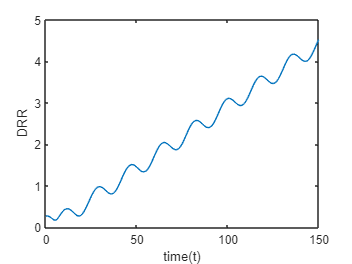

t=[(0:150)];


psi=ns*t;

for i = 1:length(t)
    Phirr(:,:,i)=[(4-3*cos(psi(i))),0,0;
        (6*(sin(psi(i))*psi(i))),1,0;
        0,0,cos(psi(i))];

    Phirv(:,:,i)=[sin(psi(i))/ns,(2-2.*cos(psi(i)))/ns,0;
        (2*cos(psi(i))-2)/ns,(4*sin(psi(i)))/ns-(3*(psi(i)))/ns,0;
        0,0,sin(psi(i))/ns];
    Dr(:,:,i) =(Phirr(:,:,i)*dr)+(Phirv(:,:,i)*dv);
end
%Phirv=[((1./ns).*(sin(psi))),(2./ns).*(1-cos(psi)),0;(2./ns).*(cos(psi)-1),((4./ns).*(sin(psi)))-((3./ns).*(psi)),0;0,0,(1./ns).*(sin(psi))]

Dr1(:,1)=Dr(1,:,:);
Dr2(:,1)=Dr(2,:,:);
Dr3(:,1)=Dr(3,:,:);
DRR=(Dr1.^2+Dr2.^2+Dr3.^2).^0.5;


plot(t,DRR)
xlabel('time(t)')
ylabel('DRR')